# Root Locus Example: ECP Control Design

Consider a proportional-only control design for the ECP system

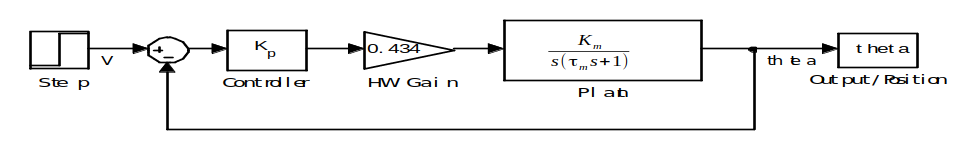

### The Root Locus Question:

As we increase the 'gain', Kp, from 0 → Infinity, how do the closed-loop poles of the system change?

### Design Constraints

Find a controller so that the closed-loop step response has

- %OS < 4.6%

- 
$$\omega_n > 0.15 \: \text{rad/s}$$


## Root Locus Process

- Write open-loop (loop-gain) transfer function in root locus form, isolating a single design parameter.

- Translate closed-loop design constraints into s-plane metrics.

- Generate the Root Locus plot

- Choose the "gain", the single design parameter, to meet the objectives.

- Verify the closed-loop performance.

### Write open-loop system in root-locus form.

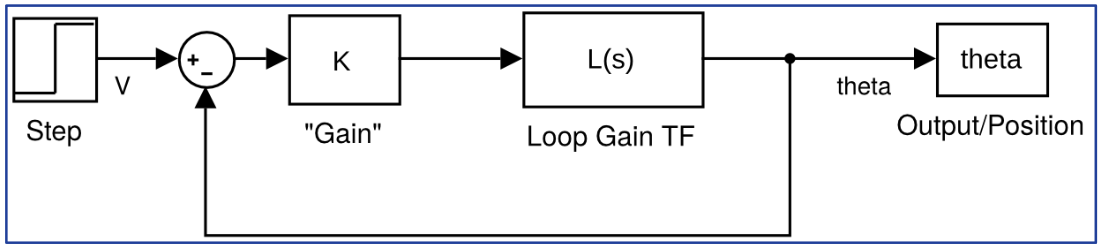

- Loop Gain TF: $0.434 \frac{k_m}{s\, (\tau_m \, s + 1)$

- Root Locus Gain: $K_p$

### Design constraints in the s-plane

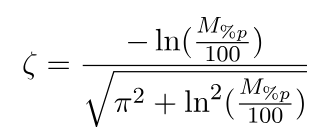

os = 4.6;
zeta = -log(os/100) / sqrt(pi^2 + log(os/100)^2)

### Generate RL

km = 25000;
tau = 4;
khw = 0.434;
L = 0.434 * tf(km,[tau 1 0]);
rlocus(L)
sgrid

### Choose gain value from RL to satisfy constraints

Will need to "pop-out" the figure window to use the data tips graphical tool.

Kp = 

### Verify the closed-loop performance

T = feedback(Kp*L, 1);
step(T)
damp(T)
stepinfo(T)